# Especies virtuales prueba

----Reading layers----


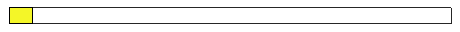

Elapsed time is 22.735550 seconds.


addpath VirtualSpeciesFunctions/
layerfolder = "Capas_Colombia_30S/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

close all

Occupation = [0.5, 0.6];
Samples = [10 50];

Samples =     10    50


alpha:0.1


Samples:10


Occupation:0.5


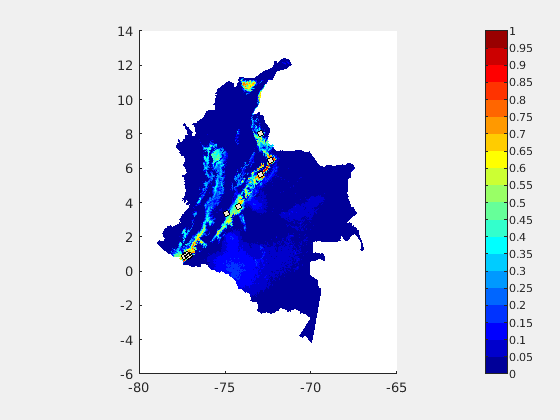

alpha:0.1


Samples:50


Occupation:0.5


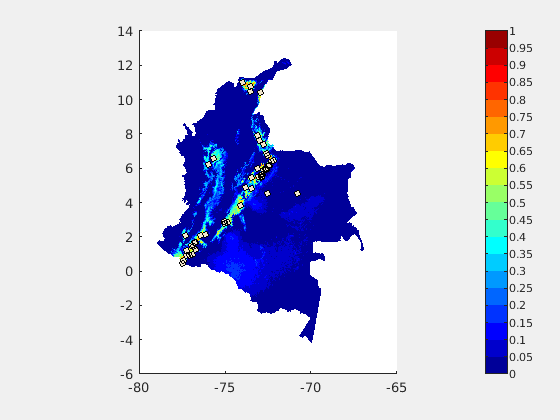

alpha:0.1


Samples:10


Occupation:0.6


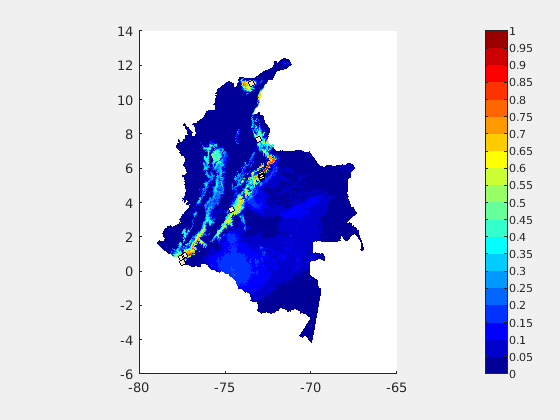

alpha:0.1


Samples:50


Occupation:0.6


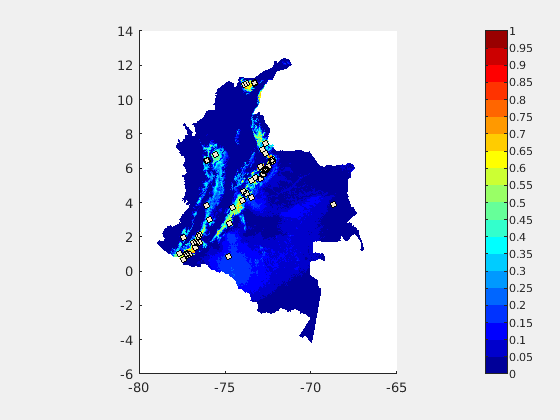

alpha:0.6


Samples:10


Occupation:0.5


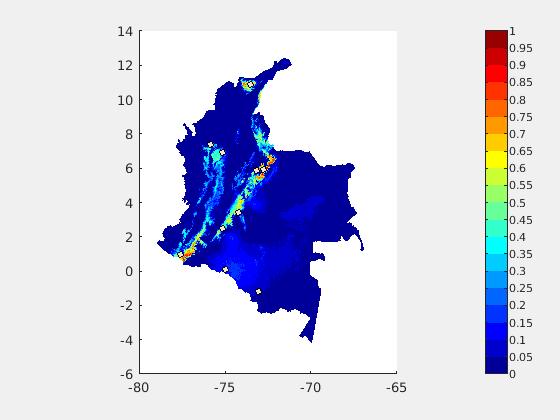

alpha:0.6


Samples:50


Occupation:0.5


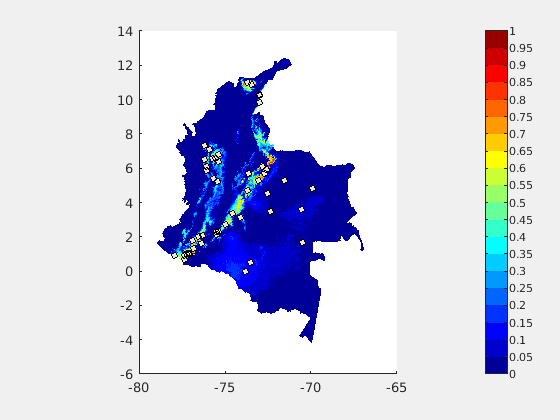

alpha:0.6


Samples:10


Occupation:0.6


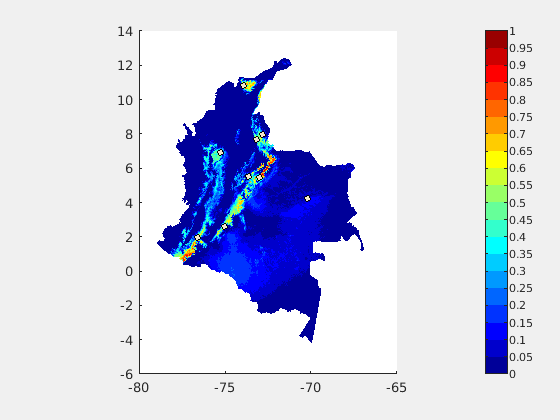

alpha:0.6


Samples:50


Occupation:0.6


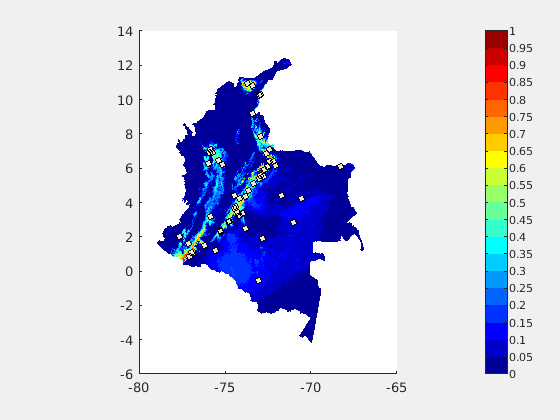

alpha:0.1


Samples:10


Occupation:0.5


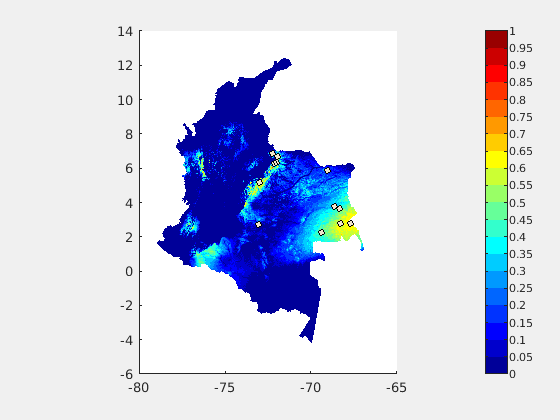

alpha:0.1


Samples:50


Occupation:0.5


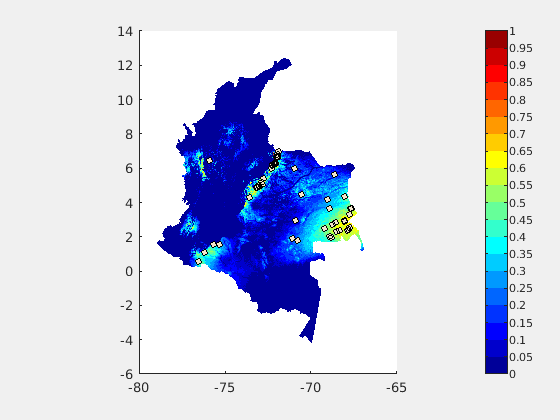

alpha:0.1


Samples:10


Occupation:0.6


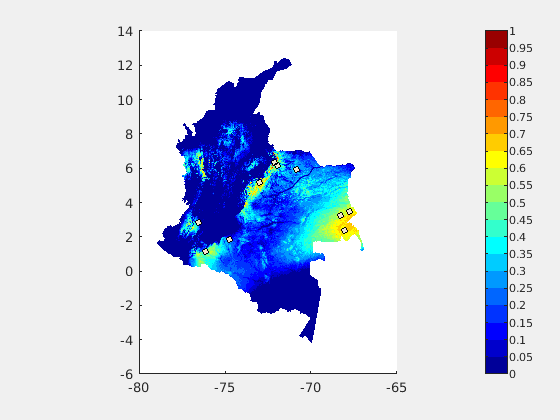

alpha:0.1


Samples:50


Occupation:0.6


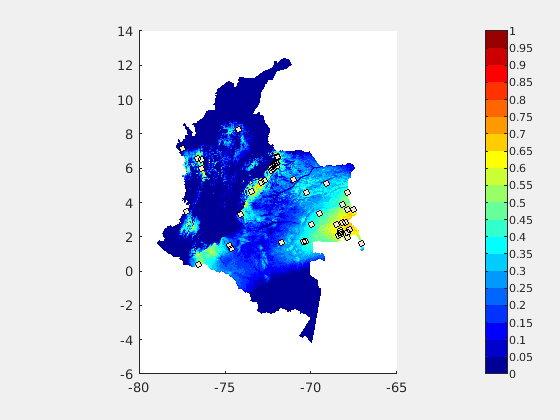

alpha:0.6


Samples:10


Occupation:0.5


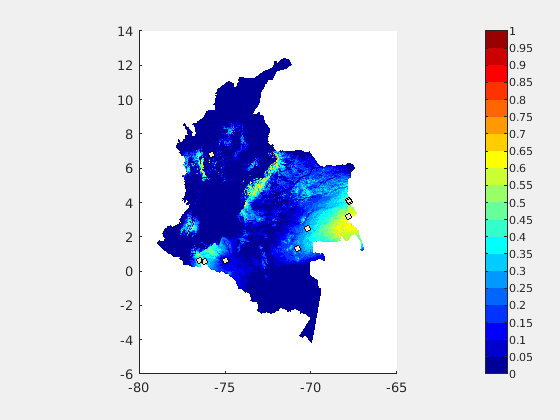

alpha:0.6


Samples:50


Occupation:0.5


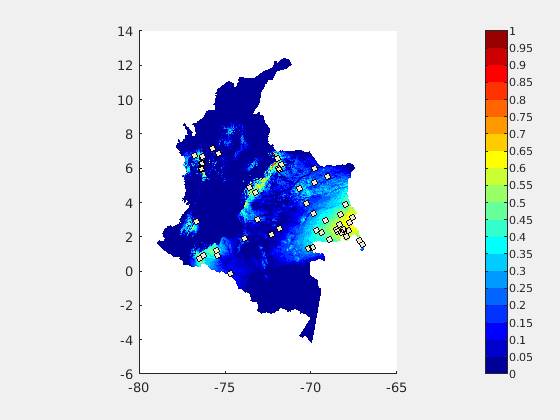

alpha:0.6


Samples:10


Occupation:0.6


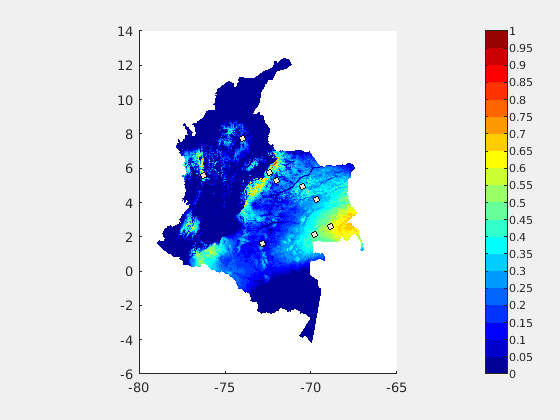

alpha:0.6


Samples:50


Occupation:0.6


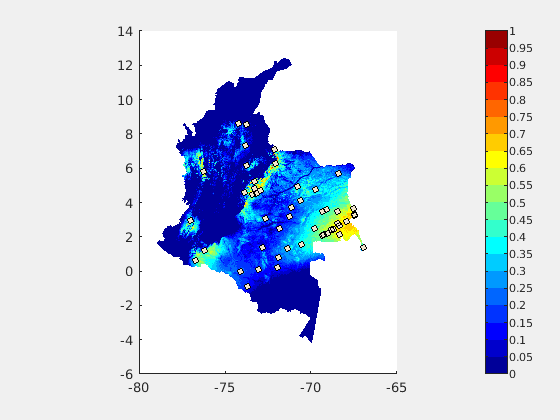

alpha:0.1


Samples:10


Occupation:0.5


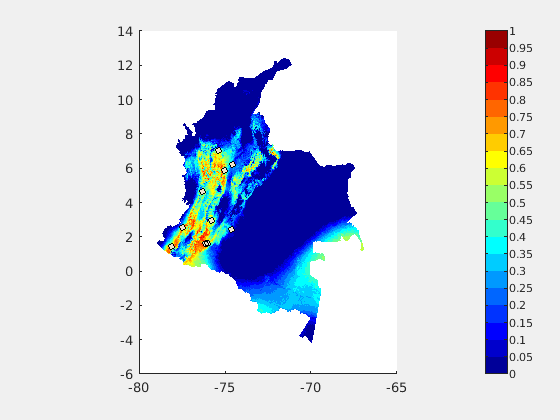

alpha:0.1


Samples:50


Occupation:0.5


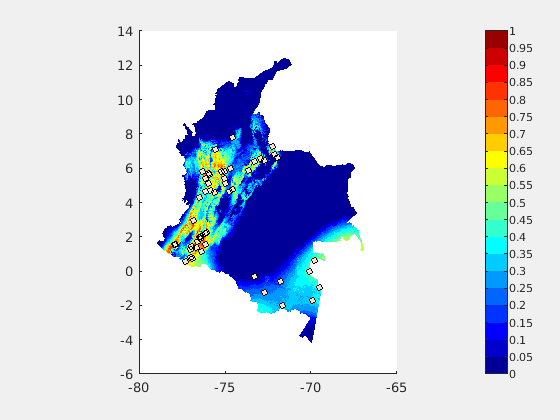

alpha:0.1


Samples:10


Occupation:0.6


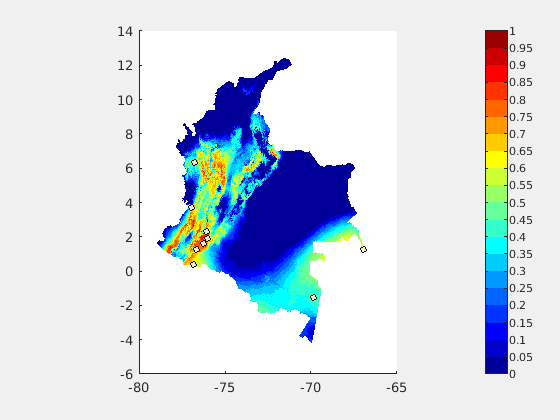

alpha:0.1


Samples:50


Occupation:0.6


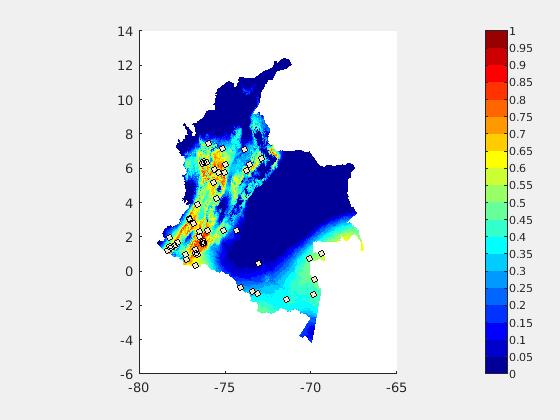

alpha:0.6


Samples:10


Occupation:0.5


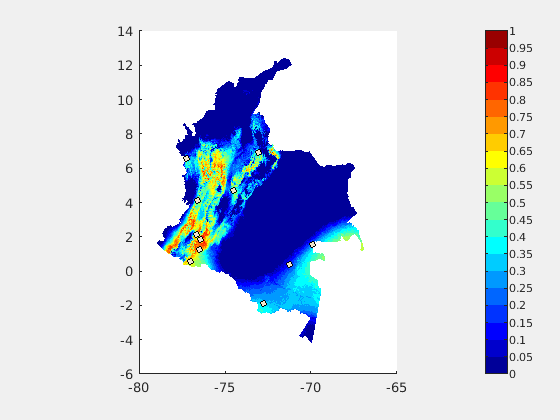

alpha:0.6


Samples:50


Occupation:0.5


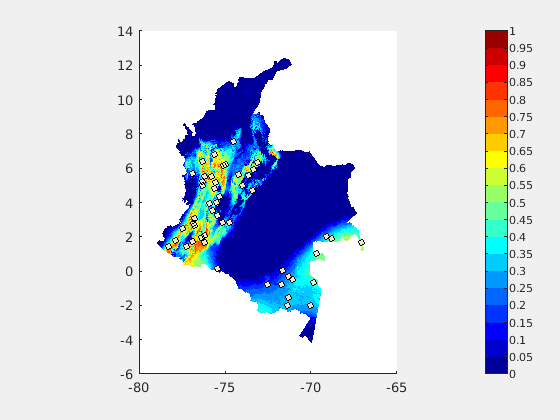

alpha:0.6


Samples:10


Occupation:0.6


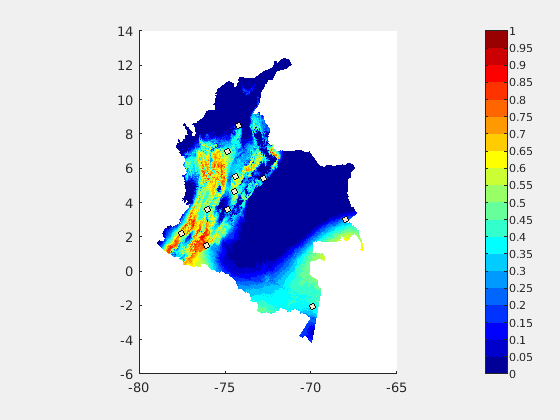

alpha:0.6


Samples:50


Occupation:0.6


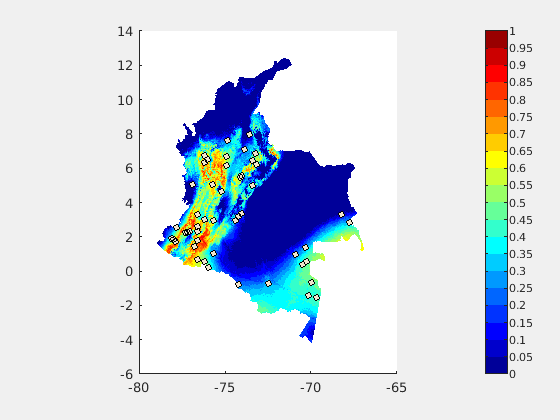

alpha = [0.1 0.6]; 
% Occupation = 0.1:0.2:0.7;            % Ocupacion terreno
% Samples = [10 50 100 1000];          % Número de puntos 
% alpha = 0 : 0.25 : 1;                % Forma de muestreo

[OccupExp, SampExp, alpExp] = meshgrid(Occupation, Samples, alpha);
OccupExp = OccupExp(:);
SampExp = SampExp(:);
alpExp = alpExp(:);

%generacion de los puntos iniciales
N = 3;
Size = Dimensions.Dimensions(2);

p = sobolset(Size);
p = scramble(p, 'MatousekAffineOwen');
Points = net(p, N);

tic
for j = 1 : N
    %initial point definition
    InfoInitialPoint = InitialPoint(Dimensions, Points(j, :)');    

    for i = 1 : length(SampExp)
        disp("alpha:" + alpExp(i))
        disp("Samples:" + SampExp(i))
        disp("Occupation:" + OccupExp(i))
        disp(" ")
        figure
        [T, NicheMap] = VirtualSpecies(Dimensions, InfoInitialPoint, SampExp(i), OccupExp(i), alpExp(i), true, 'GenSP');
        % modeling, save Metric
        drawnow
        close all
    end
end

toc

Elapsed time is 111.351104 seconds.


% writetable(T,'virtual.csv')

addpath Capas_Colombia_30S/
addpath Tool/
doc = 'virtual.csv';%Ruta al documento de texto con los registros
layerfolder = "Capas_Colombia_30S/";%route to folder with ambiental data
show = true;%para mostrar todas las figuras
data = bnm_prep(T, Dimensions, show, 0.7)

data = bnm_modeling(data, '', show)

----Finding correlation----


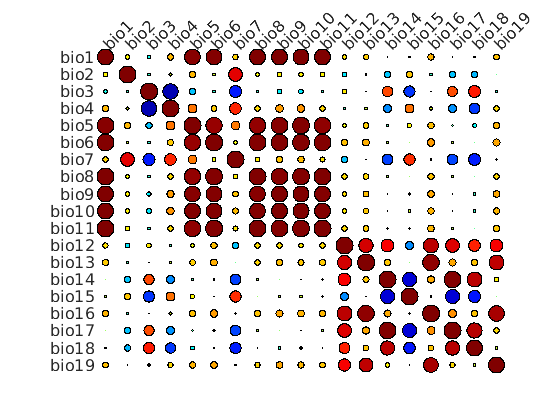

Elapsed time is 7.250606 seconds.
----Creating predictors----


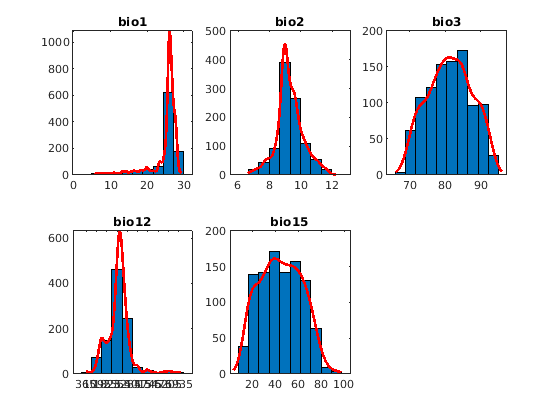

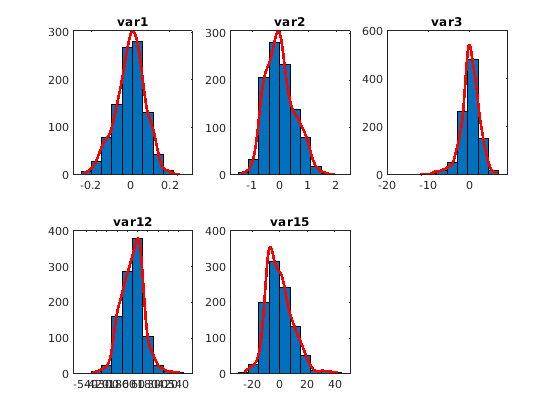

Elapsed time is 9.416698 seconds.
¡All done!


data = struct with fields:
         Tdata: [100×10 table]
    Indicators: [1 2 3 12 15]
          Vars: [1 2 3 12 15]
            T2: [1000×22 table]
             Z: [2004×1462×19 double]
             R: [3×2 double]


ModelMap = data.Map;

----Modeling----


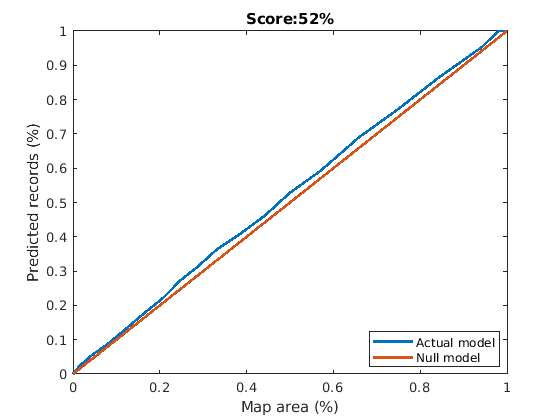

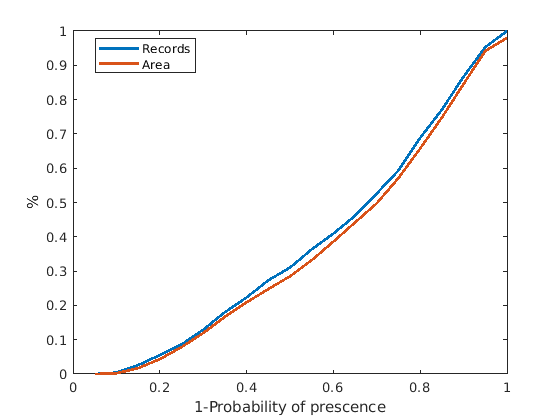

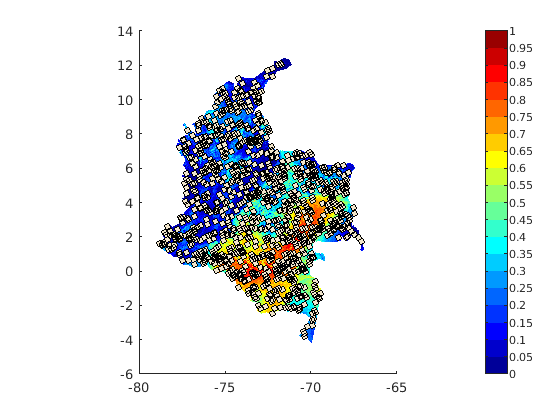

Elapsed time is 4.015563 seconds.


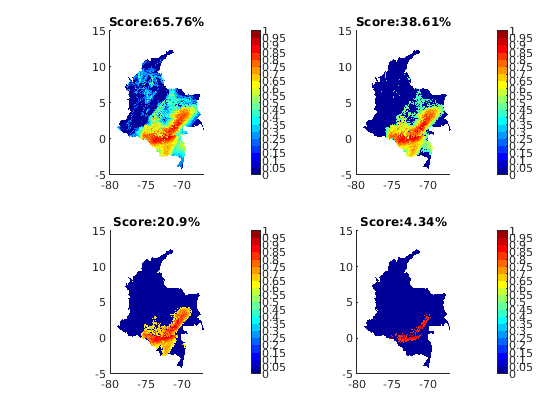

data = struct with fields:
         Tdata: [100×10 table]
    Indicators: [1 2 3 12 15]
          Vars: [1 2 3 12 15]
            T2: [1000×22 table]
             Z: [2004×1462×19 double]
             R: [3×2 double]
           Map: [2004×1462 double]
      Response: [2929848×10 double]
      Minimize: 0.9829
        Method: 4


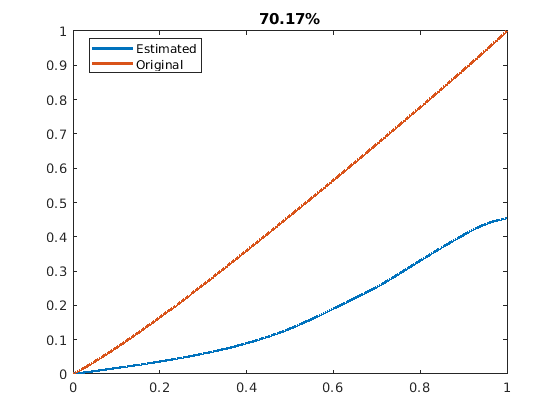

Metric = MapMetric(NicheMap, ModelMap, true);